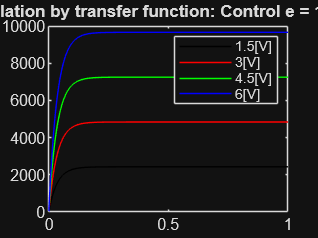

%
%  Simulation of dc_motor model by transfer function
%    Author: Keitaro Naruse
%    Date: 2023-04-10
%    You should update motor parameteres and equations
%    MIT License
%

% Motor parameres
R = 37.5;
L = 0.29 * 1E-3;
Jm = 0.015 * 1E-7;
Ki = 15400/60*2*pi;
Ke = 1/Ki;
Kt = 2.63 * 1E-3;
Tm = ( R * Jm ) / ( Ke * Kt ) ;
Te = L/R;

% Set it as transfer function
G = tf([1], [Ke*Tm*Te, Ke*Tm, Ke]);

% Simulation setting
t = [0:0.001:1];

% Control: u = 1.5
u15 = 1.5 * ones(size(t));
[y0, t] = lsim(G, u15, t);

% Control: u = 3
u30 = 3 * ones(size(t));
[y3, t] = lsim(G, u30, t);

% Control: u = 4.5
u45 = 4.5 * ones(size(t));
[y6, t] = lsim(G, u45, t);

% Control: u = 9
u60 = 6 * ones(size(t));
[y9, t] = lsim(G, u60, t);

% Plot them 
figure(1);
plot(t, y0, 'k-', t, y3, 'r-', t, y6, 'g-', t, y9, 'b-');
title('DC motor simulation by transfer function: Control e = {1.5, 3.0, 4.5, 6.0}[v]');
legend('1.5[V]', '3[V]', '4.5[V]', '6[V]');